# Image Analysis for Biometric features

Identify points in a frame that correspond the center point of a fish's head by analyzing the intensity characteristics of the larvae. The solution should not depend on threshold values that are manually determined. Investigate the accuracy of your determinations.

## Acquiring images from file

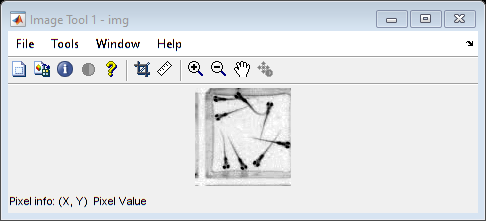

folder = '.\zebraFish\frames_grey';
filePattern = fullfile(folder, '*.png');
theFiles = dir(filePattern);
numimages = length(theFiles);

% Not fully implemented, will need to create functions to be called within
% the loop and add to a montage of images

% for i = 1:1
    i = 1;
    baseFileName = theFiles(i).name;
    fullFileName = fullfile(theFiles(i).folder, baseFileName);
    img = imread(fullFileName);
    % will call functions here to process the image
    
    imtool(img);

% end

## Convert Image to Grayscale

Despite the image already being in grayscale, matlab still considers the image an rgb even though the rgb values are all the same within each pixel. Converting the to grayscale gets rid of the rgb and allows the usage of functions that require grayscale images.

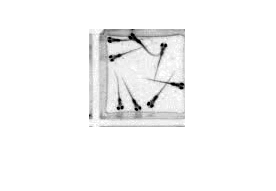

grayimg = im2gray(img);

% increase contrast of the image
grayimg = imadjust(grayimg);
imshow(grayimg);

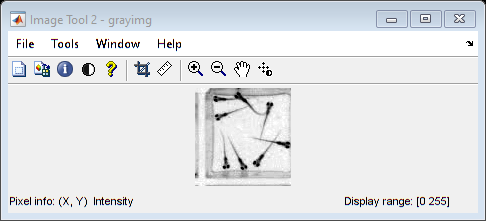

imtool(grayimg);

## Examining intensity values

Using imhist function on the grayimg in order to see the intensity value distribution of the grayscale image.

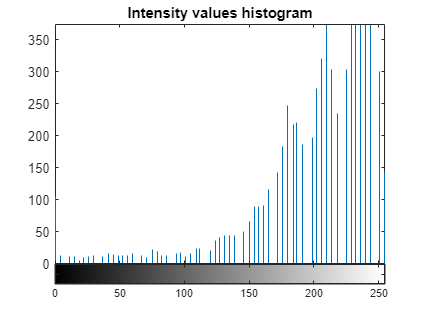

figure('Name','grayimg histogram'), imhist(grayimg);
title("Intensity values histogram");

## Thresholding the image

After using imtool and looking at the histogram to see the intensity characteristics of the fish, we decided to have two images thresholded in different ways.One image is thresheld with the value of zero since the darkest parts of the fish are its body and eyes. This helps to.

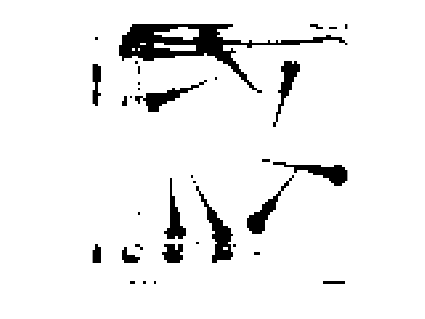

% multithresh returns the single threshold value thresh computed for the
% image using Otsu's method.
level = multithresh(grayimg);

% Segment the image into two regions using imquantize , specifying the threshold level returned by multithresh.
threshimg =  imquantize(grayimg,level);

% Need to convert the image to rgb than grayscale because the image needs
% be formatted in this order otherwise it will not work
thrimg = label2rgb(threshimg);
thrimg = im2gray(thrimg);

% finally threshold the image
threshimg = imbinarize(thrimg);
imshow(threshimg);


% flipping the image
complementImg = imcomplement(threshimg)

complementImg = 98×96 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0

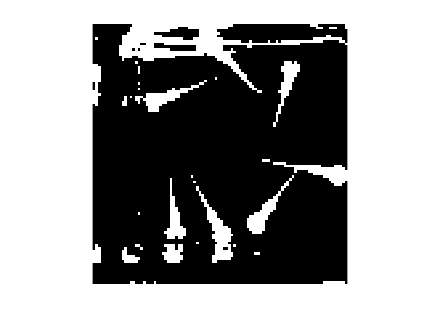

imshow(complementImg);

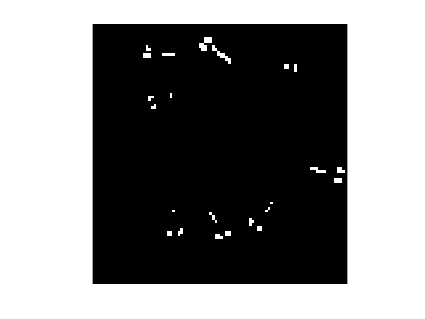


% Creating a thresheld image which only tries to get the eyes
BW = imbinarize(grayimg,0);
BW = imcomplement(BW);
imshow(BW);

## Morphology

Using morpholoy to get rid of noise such as the dots and the line. Imopen is an erosion followed bya a dilation on the image. Erosion as the name suggests, erodes the pixels within the image down to a structure such as a square. After the erosion, open will dilate the eroded image, which expands the pixels into a structure. 

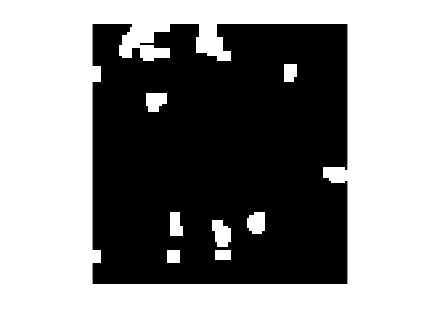

% Setting the bounds for which imopen will accept how large a square can be
se = strel("square", 4);
openimg = imopen(complementImg, se);
imshow(openimg);

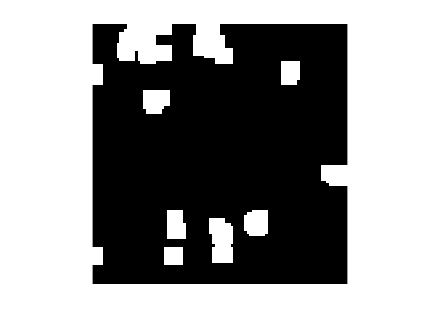


% dilating the image a little more because the heads are a bit too small and may miss an eye.
openimg = imdilate(openimg,strel("square", 3));
imshow(openimg);

## 8 Connectivity

Using 8 connectivity to determine what counts as part of the same region. 8 connectivity means that are touching corners, can be classified as the same object within the image.

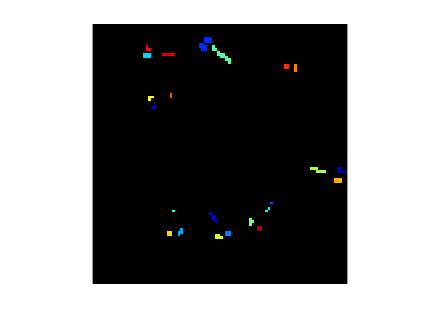

% bwconncomp will find the connected components in a binary image.
objopenimg = bwconncomp(openimg);
objBW = bwconncomp(BW);

% labelmatrix creates a label matrix form the connected component structure
% returned by bwwconncomp.
labelopenimg = labelmatrix(objopenimg);
labelBW = labelmatrix(objBW);

% extracting the size from the connected component structure which is the
% number of objects that it has detected.
numbodies = objopenimg.NumObjects;
numeyes = objBW.NumObjects;

% Before determining which eyes belong to which body
imshow(label2rgb(labelBW,'jet','k','shuffle'));

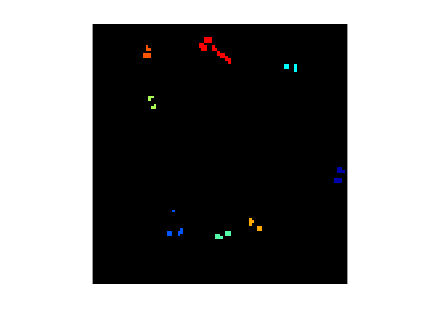


% go through all the eyes and see if they are inside a body
% If true, relabel the eye to the same number as the body.
% If false, set the object to 0, which essentially deletes the object.
for i = 1:numeyes
    for n = 1:numbodies
        if all(ismember(objBW.PixelIdxList{i},objopenimg.PixelIdxList{n}))
            labelBW(objBW.PixelIdxList{i}) = n;
            break;
        elseif n == numbodies
            labelBW(objBW.PixelIdxList{i}) = 0;
        end
    end
end

imshow(label2rgb(labelBW,'jet','k','shuffle'));

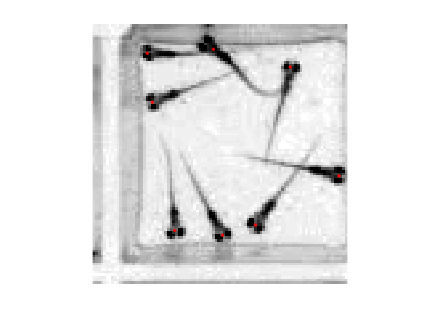


% Using regionprops on the new matrix to get the centroid of each pair of
% eyes
stats = regionprops(labelBW, 'Centroid');
centroids = cat(1,stats.Centroid);

% Getting the original image to plot points onto
imshow(grayimg)
hold on
% taking the points that centroids has stored for us and plotting them to
% the original image.
plot(centroids(:,1),centroids(:,2),'r.');
frameStructure = getframe;
displayedImage = getimage();
hold off


% saveas();

## Intersection of matrices

Using the intersection function to find the objects within the first image that are in the same coordinates as the second image. This should get rid of the lines from the body and only keep the eyes as objects.

% intersectionOfimgbw = intersect(labelopenimg, labelBW);

## Edge Detection

Using edge detection to see if it helps separate the fish from the background.

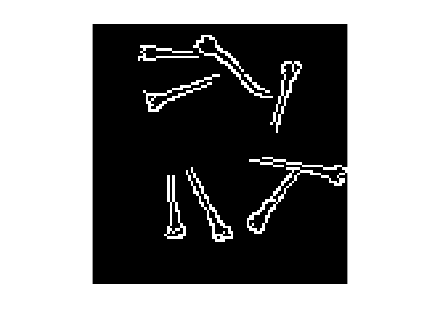

edgeimg = edge(grayimg, 'approxcanny');
imshow(edgeimg);

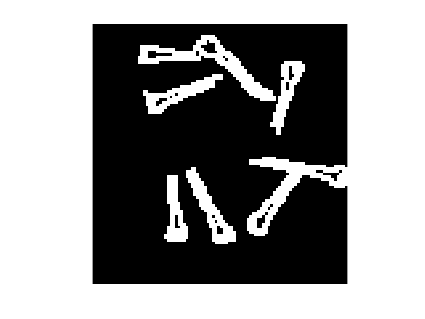


se = strel("square",2);
dilimg = imdilate(edgeimg,se);
imshow(dilimg);

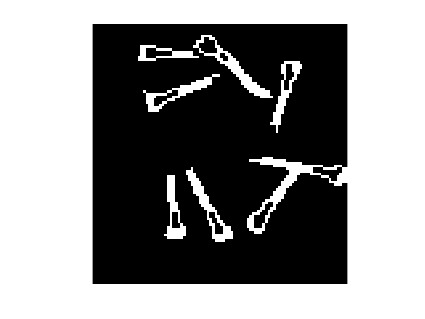


se = strel("square",2);
eroimg = imerode(dilimg, se);
imshow(eroimg);

dilimg3 = imdilate(edgeimg,se);
imshow(dilimg3);